clear;
cd 'C:\Users\Admin\OneDrive\Документы\UNI_stuff\ИКИ  projects';

pic = input('Enter a number from 1 to 4 to choose a picture: ');

prompt = 'In Command Window type "0" if loop length will be calculated via diameter and "1" otherwise: ';
n = input(prompt);

prompt = 'click - number of clicks: ';
click = input(prompt);

for i = 1:1:click
    
    switch pic
    case 1
         imshow 20_01_active_region.png
    case 2
        imshow 15_02_active_region.png
    case 3
        imshow 07_01_active_region.png
    case 4
        imshow 02_01_active_region.png
    otherwise
        disp('this picture does not exist')
    end
     
    [x(:,i), y(:,i), P_temp] = impixel; % push left mouse button to select first point and right to select the second point
    
    clear P_temp
    R(i, 1) = sqrt( (x(1, i) - x(2, i))^2 + (y(1, i) - y(2, i))^2 ); % diametr / radius length depends on loop approximation variant chosen
    X = ['click ', num2str(i),' out of ', num2str(click)];
    disp(X)
end
R = mean(R) % average value of diametr / radius

if (n == 0) % diametr
    L = pi*R/2;
else 
    L = pi*R;
end
% L
Lm = 725*10^3*L*0.6;
L_Mm = Lm/10^6;

disp('loop length is: ')
disp([num2str(L) ' pixels'])
disp([num2str(Lm) ' m'])
disp([num2str(L_Mm) ' Mm'])
save('L_Mm.mat','L_Mm')
% save ('L_Mm.mat', 'L_Mm') % saving loop length as martix

clear
imshow 20_01_33_td_map.png
[x20,y20,P20] = impixel; % left mouse button to select points, right to close

save('x20.mat','x20');
save('y20.mat','y20');

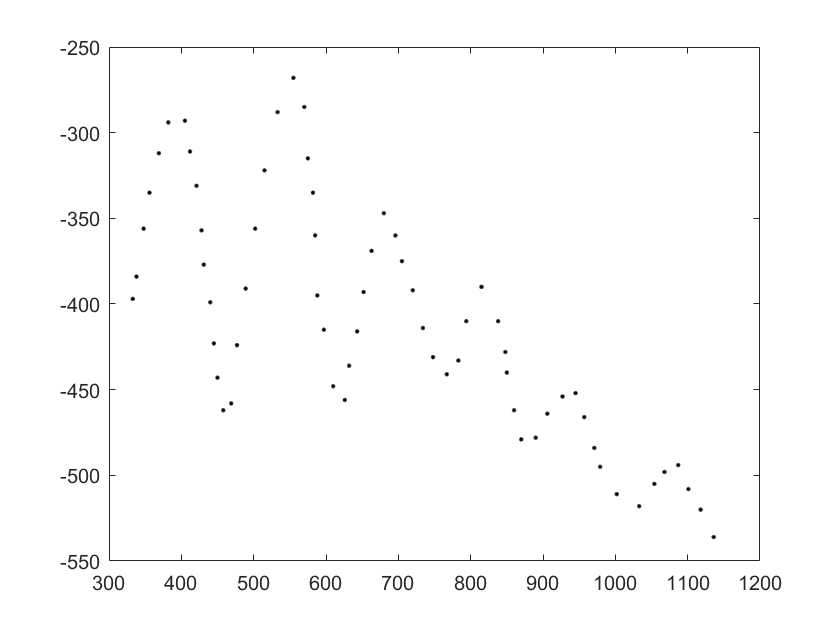

clear
load('x20.mat');
load('y20.mat');
y20 = -y20;
plot(x20, y20, '.k');

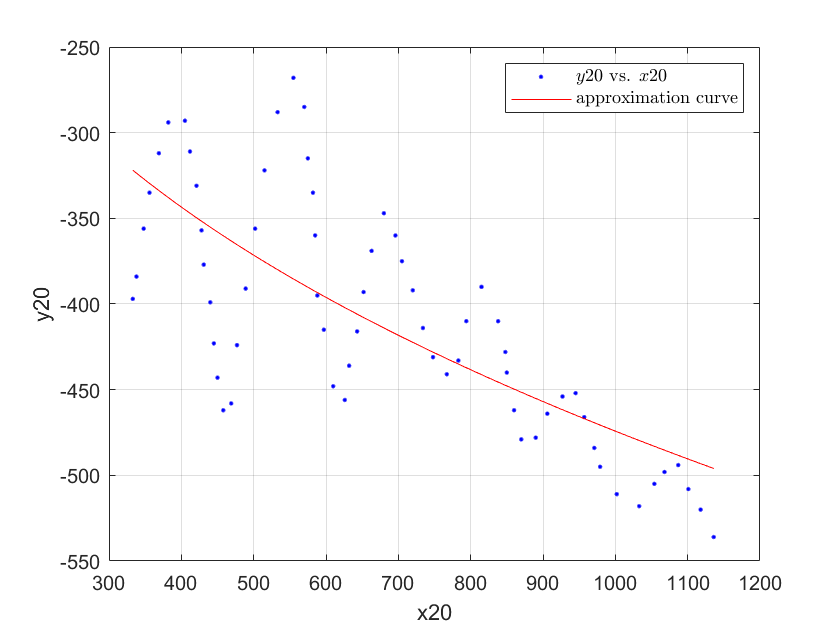

% 20_01_33_td_map.png approximation curve
clear
load('x20.mat');
load('y20.mat');
y20 = -y20;

[xData, yData] = prepareCurveData( x20, y20 );

% Set up fittype and options.
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.957506835434298 0.964888535199277];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, '$y20$ vs. $x20$', 'approximation curve', 'Location', 'NorthEast', 'Interpreter', 'Latex' );
% Label axes
xlabel( 'x20', 'Interpreter', 'none' );
ylabel( 'y20', 'Interpreter', 'none' );
grid on

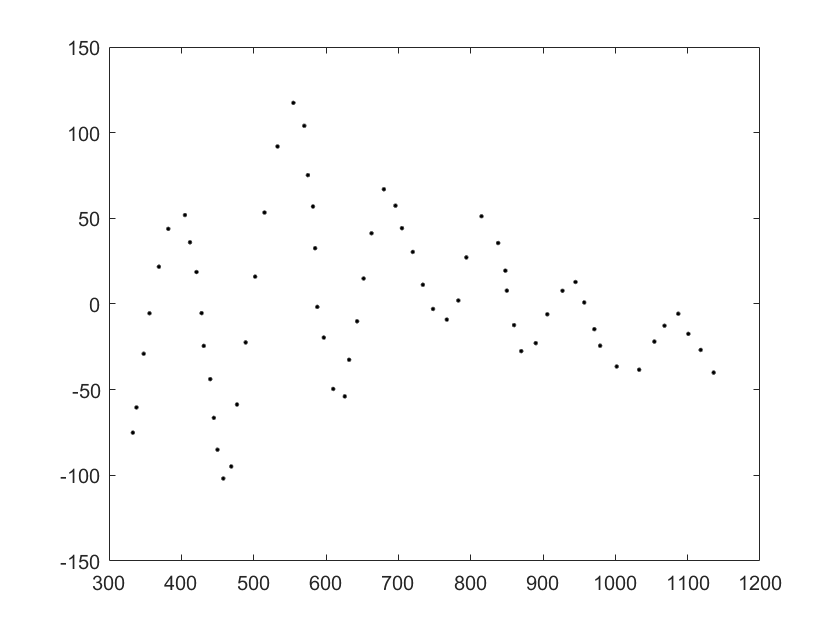


y20_new = y20 - fitresult(x20);
figure
plot(x20,y20_new,'k.')

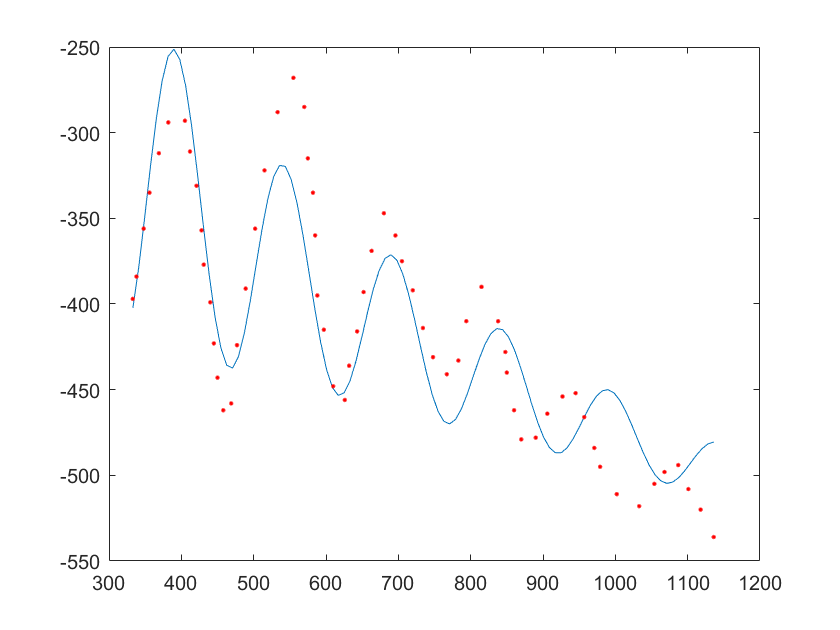


[xData, yData] = prepareCurveData( x20, y20_new );
ft = fittype( 'a*sin(b*x+c)*exp(-d*x)', 'independent', 'x', 'dependent', 'y' );
excludedPoints = excludedata( xData, yData, 'Indices', [49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 -Inf -Inf -Inf];
opts.StartPoint = [10 0.04356 0.54 1e-08];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult1, gof1] = fit( xData, yData, ft, opts );

% Plot fit with data.
h = plot( fitresult1, xData, yData, excludedPoints);

% Label axes
xlabel( '$x_{20}$', 'Interpreter', 'latex' );
ylabel( '$y_{20}$', 'Interpreter', 'latex' );
grid on

xtimes = linspace(min(x20),max(x20),100);
ytimes = fitresult1(xtimes) + fitresult(xtimes);
figure
plot(xtimes,ytimes)
hold on
plot(x20,y20,'r.')

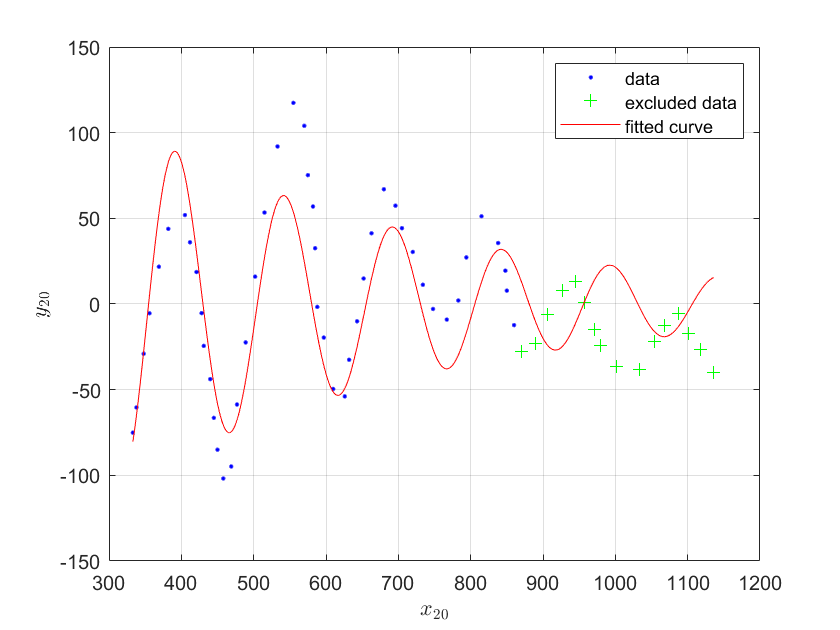


c = coeffvalues(fitresult1);
P = 2*pi/c(2)*12/60;

figure
imshow 20_01_33_td_map.png

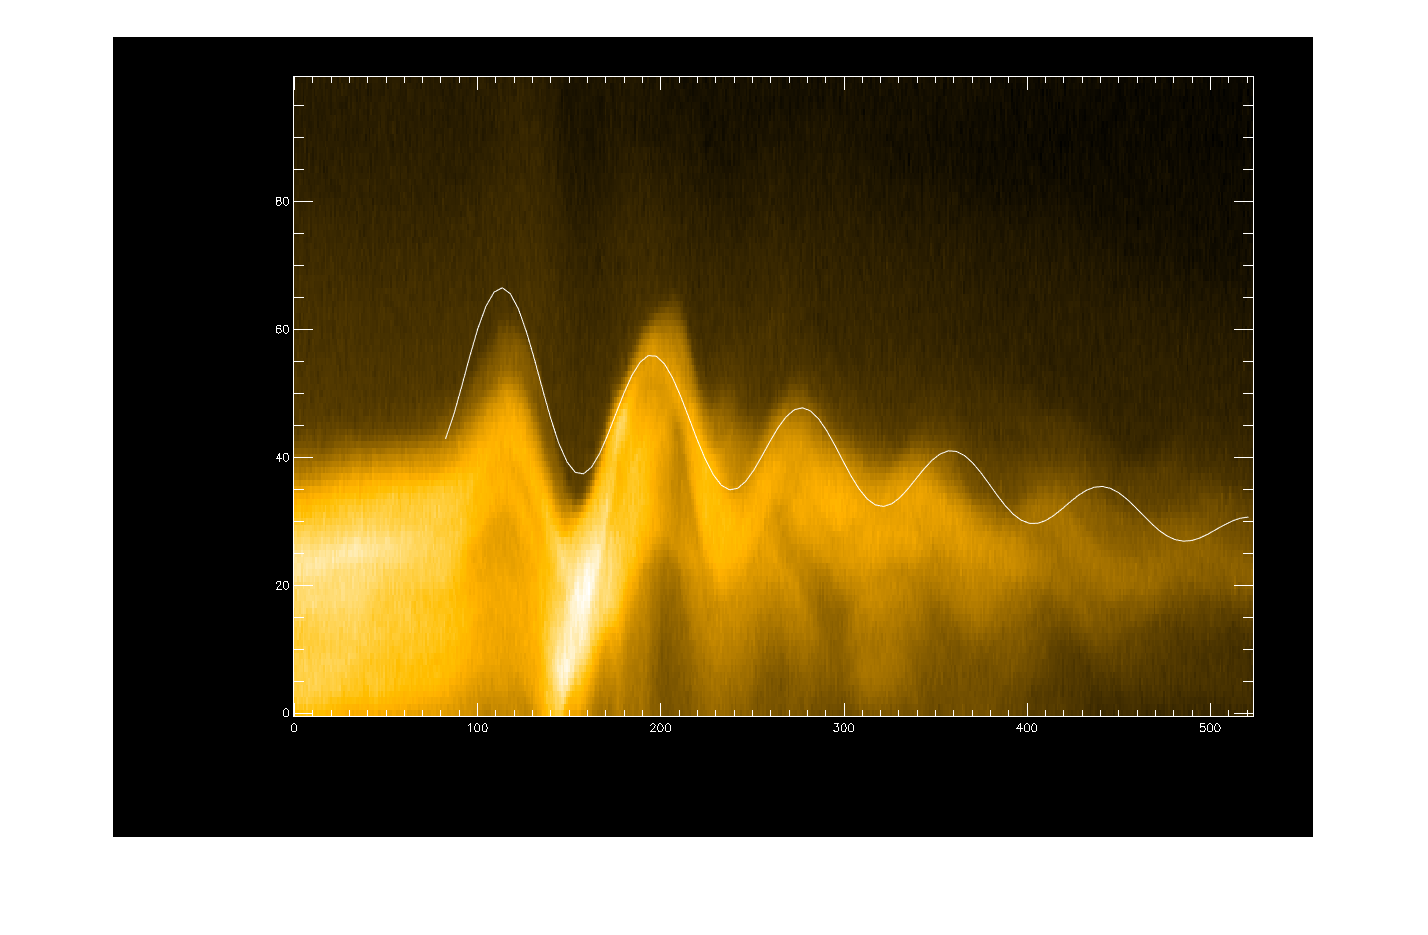

hold on
ytimes=-ytimes;
plot(xtimes,ytimes, 'r')

% 02_01_50_td_map.png approximation curve
clear
imshow 02_01_50_td_map.png
[x2,y2,P2] = impixel; % left mouse button to select points, right to close

save('x2.mat','x2');
save('y2.mat','y2');

clear
load('x2.mat');
load('y2.mat');
y2 = -y2;
plot(x2, y2, '.k');
grid on

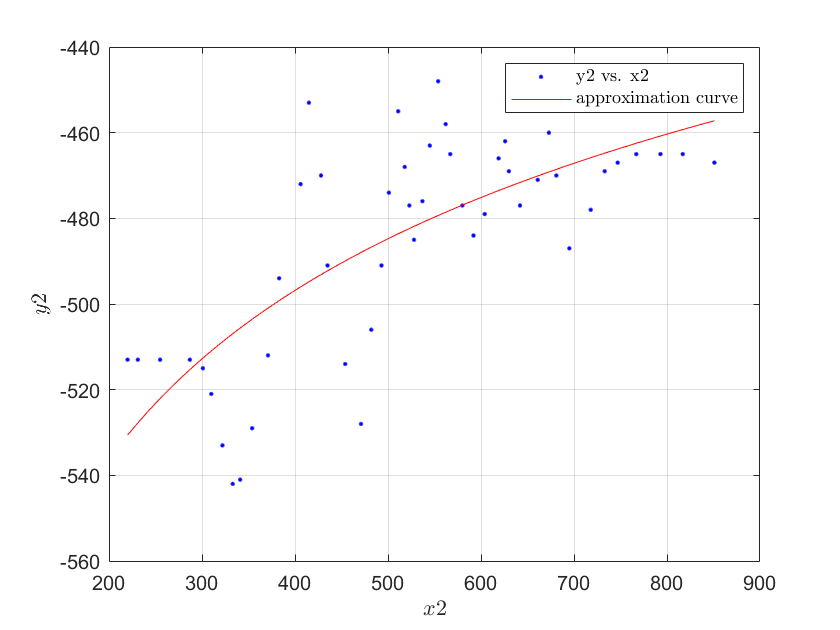

clear
load('x2.mat');
load('y2.mat');
y2 = -y2;
[xData, yData] = prepareCurveData( x2, y2 );

% Set up fittype and options.
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.913375856139019 0.63235924622541];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'y2 vs. x2', 'approximation curve', 'Location', 'NorthEast', 'Interpreter', 'Latex' );
% Label axes
xlabel( '$x2$', 'Interpreter', 'latex' );
ylabel( '$y2$', 'Interpreter', 'latex' );
grid on

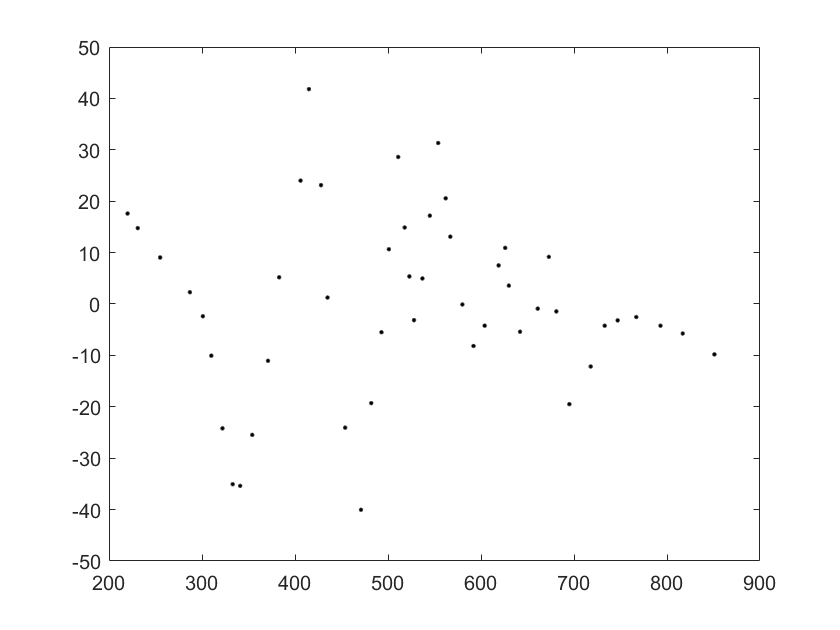


y2_new = y2 - fitresult(x2);
figure
plot(x2,y2_new,'k.')

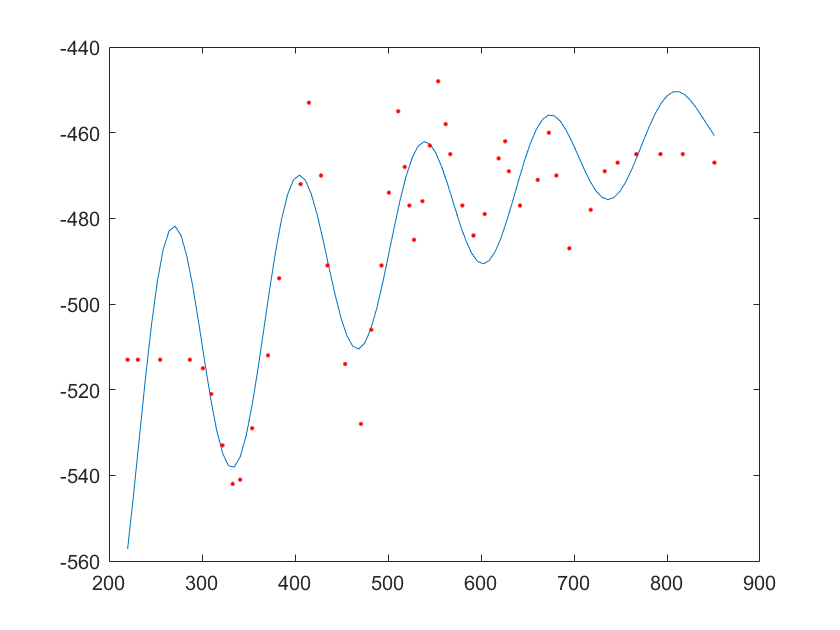


[xData, yData] = prepareCurveData( x2, y2_new );

% Set up fittype and options.
ft = fittype( 'a*sin(b*x+c)*exp(-d*x)', 'independent', 'x', 'dependent', 'y' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [10 0.04789 0.24 0.001];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult1, gof1] = fit( xData, yData, ft, opts );

h = plot( fitresult1, xData, yData, excludedPoints );
legend( h, '$y2_{new}$ vs. $x2$', 'Excluded $y2_{new}$ vs. $x2$', 'approximation curve', 'Location', 'NorthEast', 'Interpreter', 'latex' );
% Label axes
xlabel( '$x2$', 'Interpreter', 'latex' );
ylabel( '$y2_{new}$', 'Interpreter', 'latex' );

xtimes = linspace(min(x2),max(x2),100);
ytimes = fitresult1(xtimes) + fitresult(xtimes);
figure
plot(xtimes,ytimes)
hold on
plot(x2,y2,'r.')

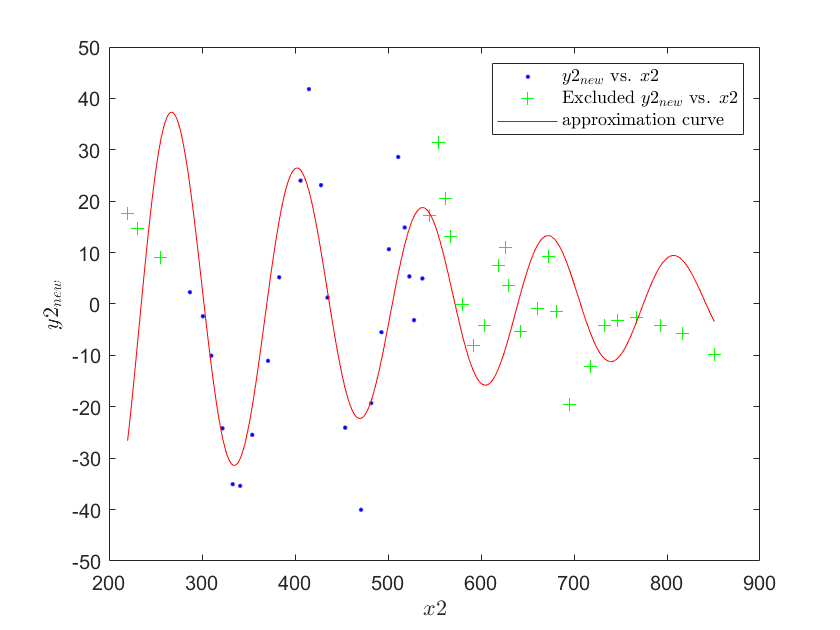


c = coeffvalues(fitresult1);
P = 2*pi/c(2)*12/60;

figure
imshow 02_01_50_td_map.png

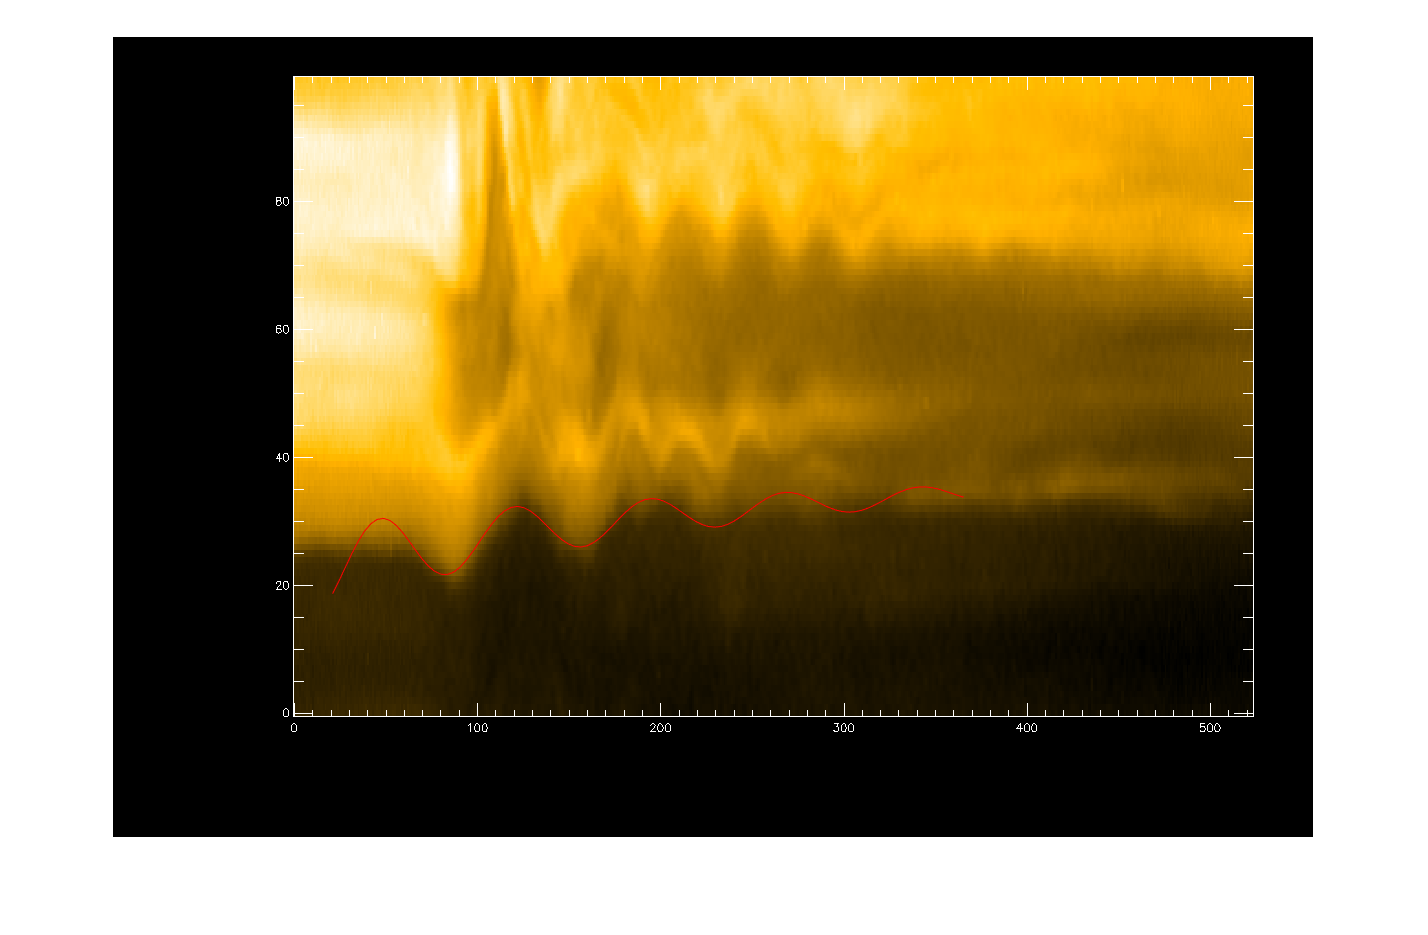

hold on
ytimes=-ytimes;
plot(xtimes,ytimes, 'r')

% 15_02_27_td_map.png approximation curve
clear
imshow 15_02_27_td_map.png
[x15,y15,P] = impixel; % left mouse button to select points, right to close

save('x15.mat','x15');
save('y15.mat','y15');

clear
load('x15.mat');
load('y15.mat');
y15 = -y15;
plot(x15, y15, '.k');
grid on

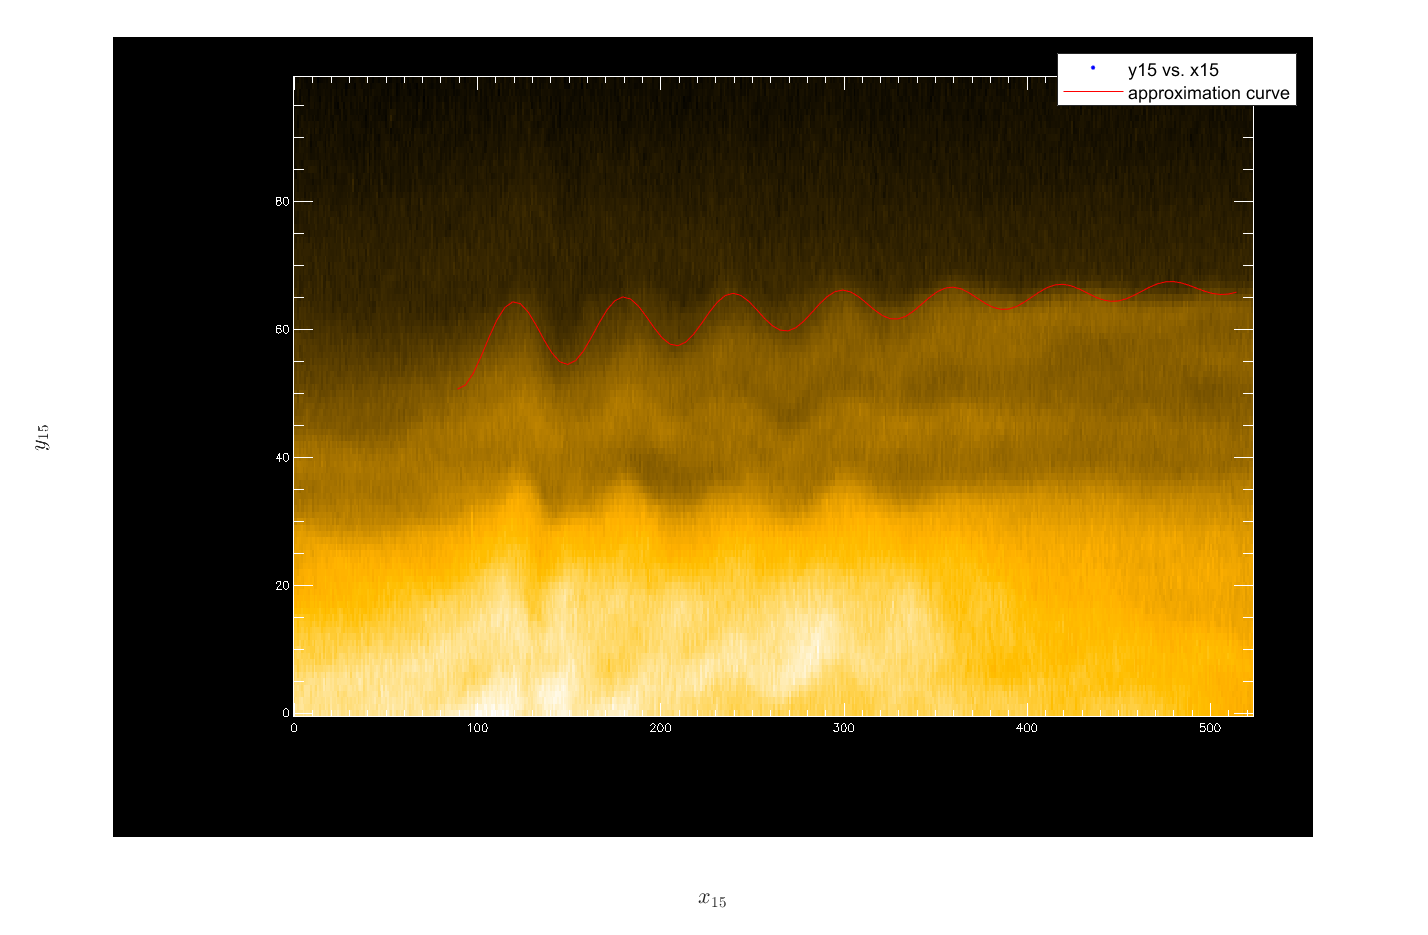

clear
load('x15.mat');
load('y15.mat');
y15 = -y15;
[xData, yData] = prepareCurveData( x15, y15 );

% Set up fittype and options.
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.913375856139019 0.63235924622541];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );


h = plot( fitresult, xData, yData );
legend( h, 'y15 vs. x15', 'approximation curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( '$x_{15}$', 'Interpreter', 'latex' );
ylabel( '$y_{15}$', 'Interpreter', 'Latex' );
grid on

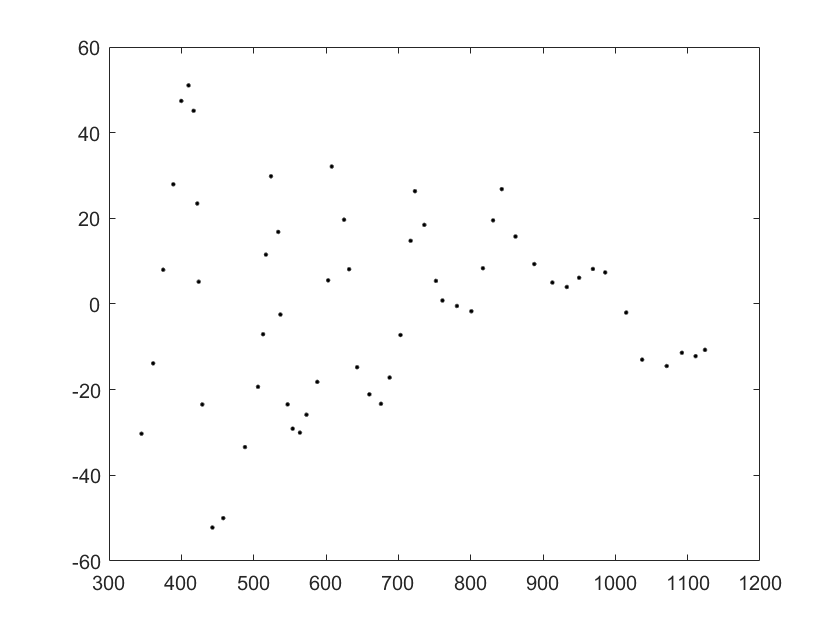


y15_new = y15 - fitresult(x15);
figure
plot(x15,y15_new,'k.')

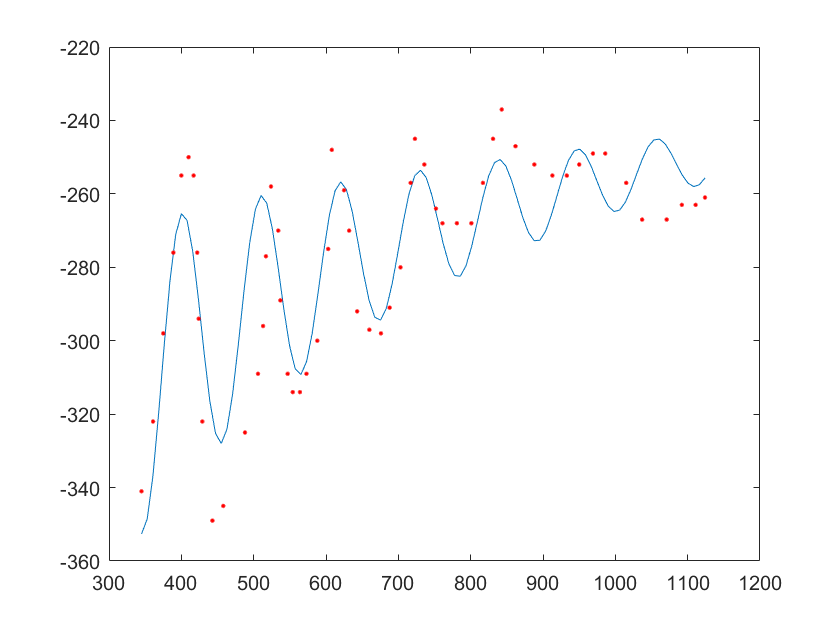


[xData, yData] = prepareCurveData( x15, y15_new );

% Set up fittype and options.
ft = fittype( 'a*sin(-b*x+c)*exp(-d*x)', 'independent', 'x', 'dependent', 'y' );
excludedPoints = excludedata( xData, yData, 'Indices', [36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 -Inf -Inf -Inf];
opts.StartPoint = [10 0.05767 0.325 1e-07];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult1, gof1] = fit( xData, yData, ft, opts );

h = plot( fitresult1, xData, yData, excludedPoints );
legend( h, 'y15_new vs. x15', 'Excluded y15_new vs. x15', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );

xlabel( '$x_15$', 'Interpreter', 'latex' );
ylabel( '$y_{15new}$', 'Interpreter', 'latex' );
grid on

xtimes = linspace(min(x15),max(x15),100);
ytimes = fitresult1(xtimes) + fitresult(xtimes);
figure
plot(xtimes,ytimes)
hold on
plot(x15,y15,'r.')

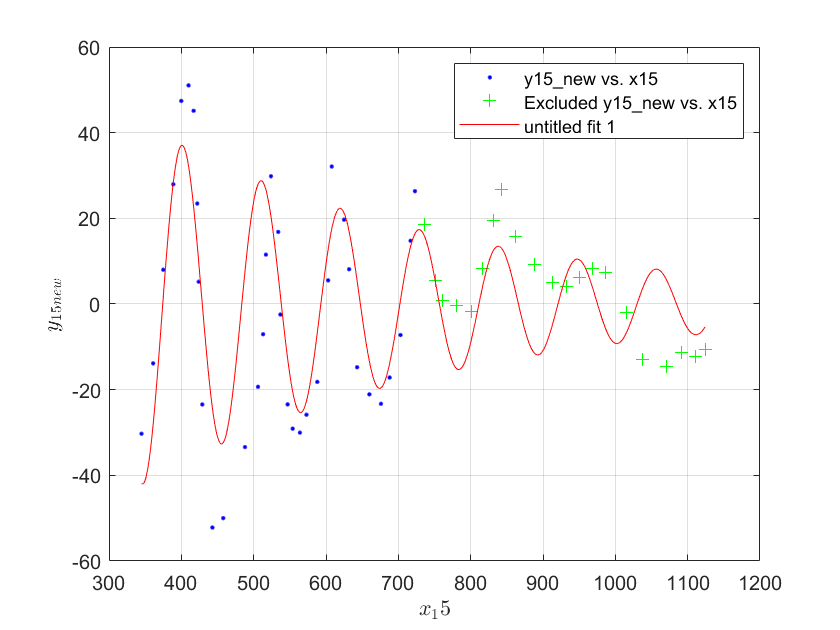


c = coeffvalues(fitresult1);
P = 2*pi/c(2)*12/60;

figure
imshow 15_02_27_td_map.png

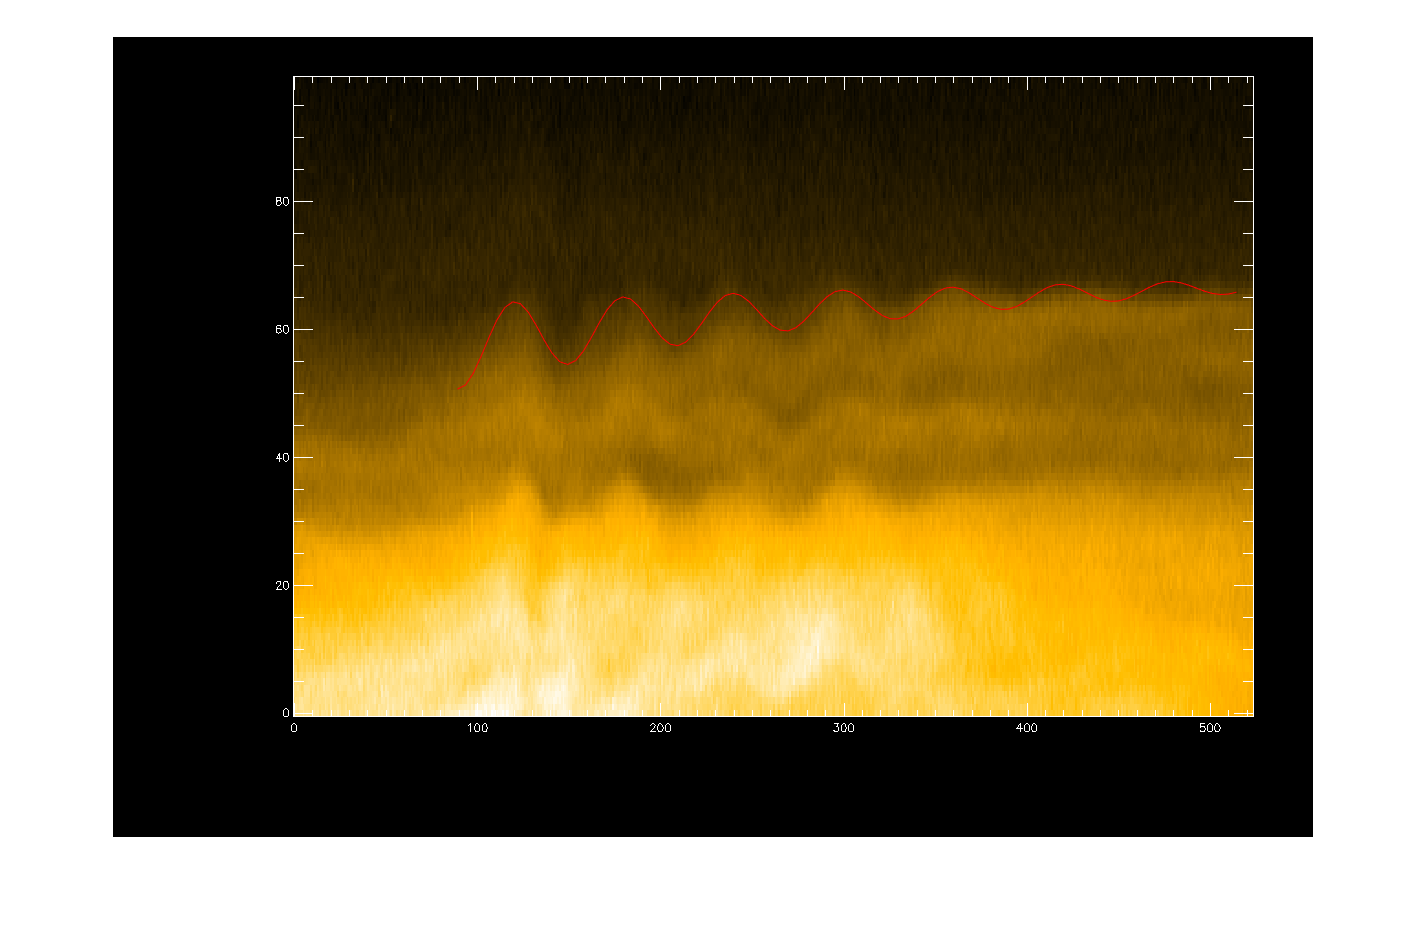

hold on
ytimes=-ytimes;
plot(xtimes,ytimes, 'r')

% 07_01_30_td_map.png approximation curve
clear
imshow 07_01_30_td_map.png
[x7,y7,P] = impixel; % left mouse button to select points, right to close

save('x7.mat','x7');
save('y7.mat','y7');

clear
load('x7.mat');
load('y7.mat');
y7 = -y7;
plot(x7, y7, '.k');
grid on

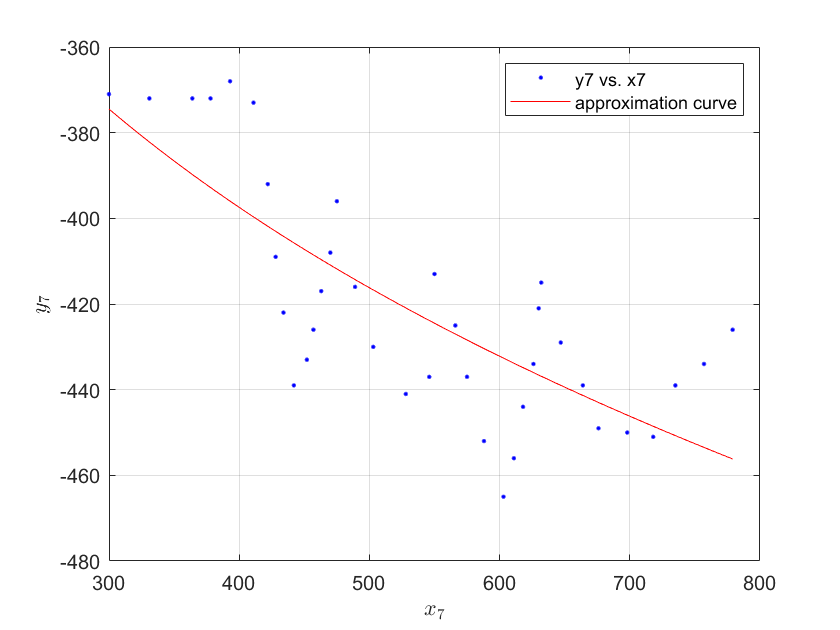

clear
load('x7.mat');
load('y7.mat');
y7 = -y7;
[xData, yData] = prepareCurveData( x7, y7 );

% Set up fittype and options.
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.933993247757551 0.678735154857773];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'y7 vs. x7', 'approximation curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( '$x_7$', 'Interpreter', 'Latex' );
ylabel( '$y_7$', 'Interpreter', 'Latex' );
grid on

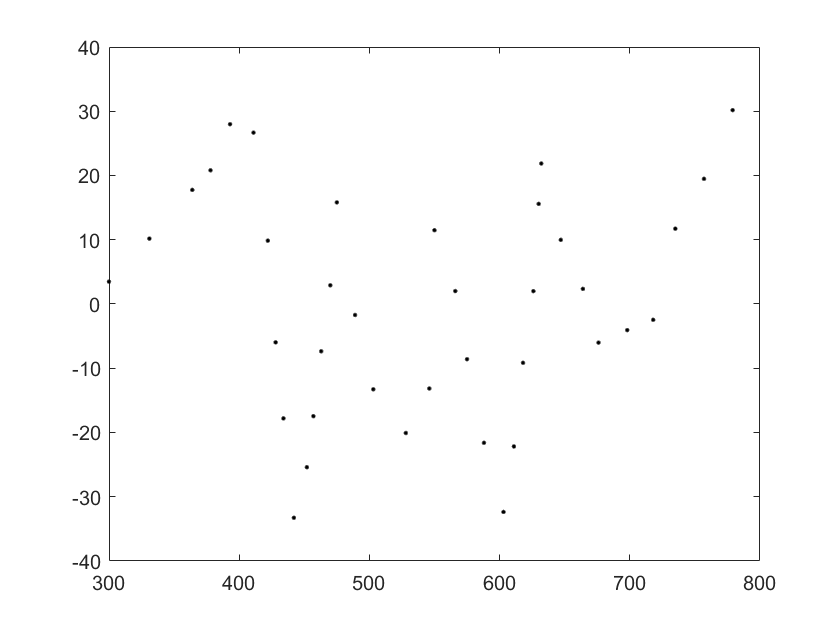


y7_new = y7 - fitresult(x7);
figure
plot(x7,y7_new,'k.')

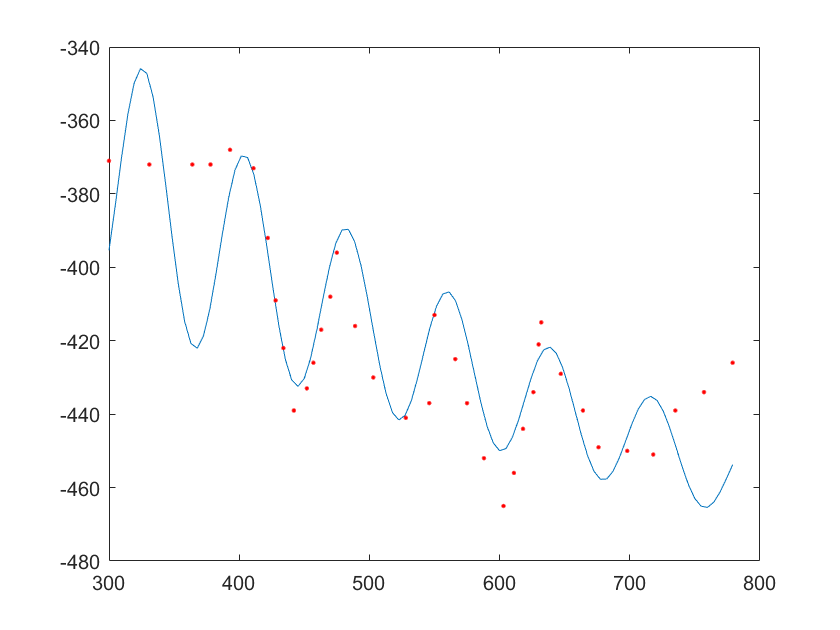


[xData, yData] = prepareCurveData( x7, y7_new );

% Set up fittype and options.
ft = fittype( 'a*sin(-b*x+c)*exp(-d*x)', 'independent', 'x', 'dependent', 'y' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 30 31 32 33 34 35 36 37] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 -Inf -Inf -Inf];
opts.StartPoint = [10 0.04686 0.7416 1e-05];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult1, gof1] = fit( xData, yData, ft, opts );

h = plot( fitresult1, xData, yData, excludedPoints );
legend( h, 'y7_new vs. x7', 'Excluded y7_new vs. x7', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( '$x_7$', 'Interpreter', 'latex' );
ylabel( '$y_{7new}$', 'Interpreter', 'latex' );
grid on

xtimes = linspace(min(x7),max(x7),100);
ytimes = fitresult1(xtimes) + fitresult(xtimes);
figure
plot(xtimes,ytimes)
hold on
plot(x7,y7,'r.')

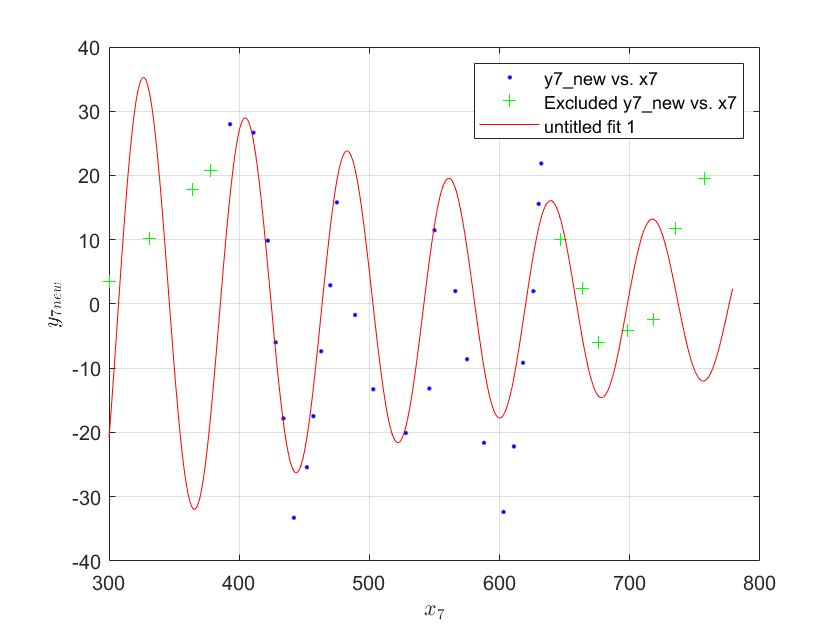


c = coeffvalues(fitresult1);
P = 2*pi/c(2)*12/60;

figure
imshow 07_01_30_td_map.png

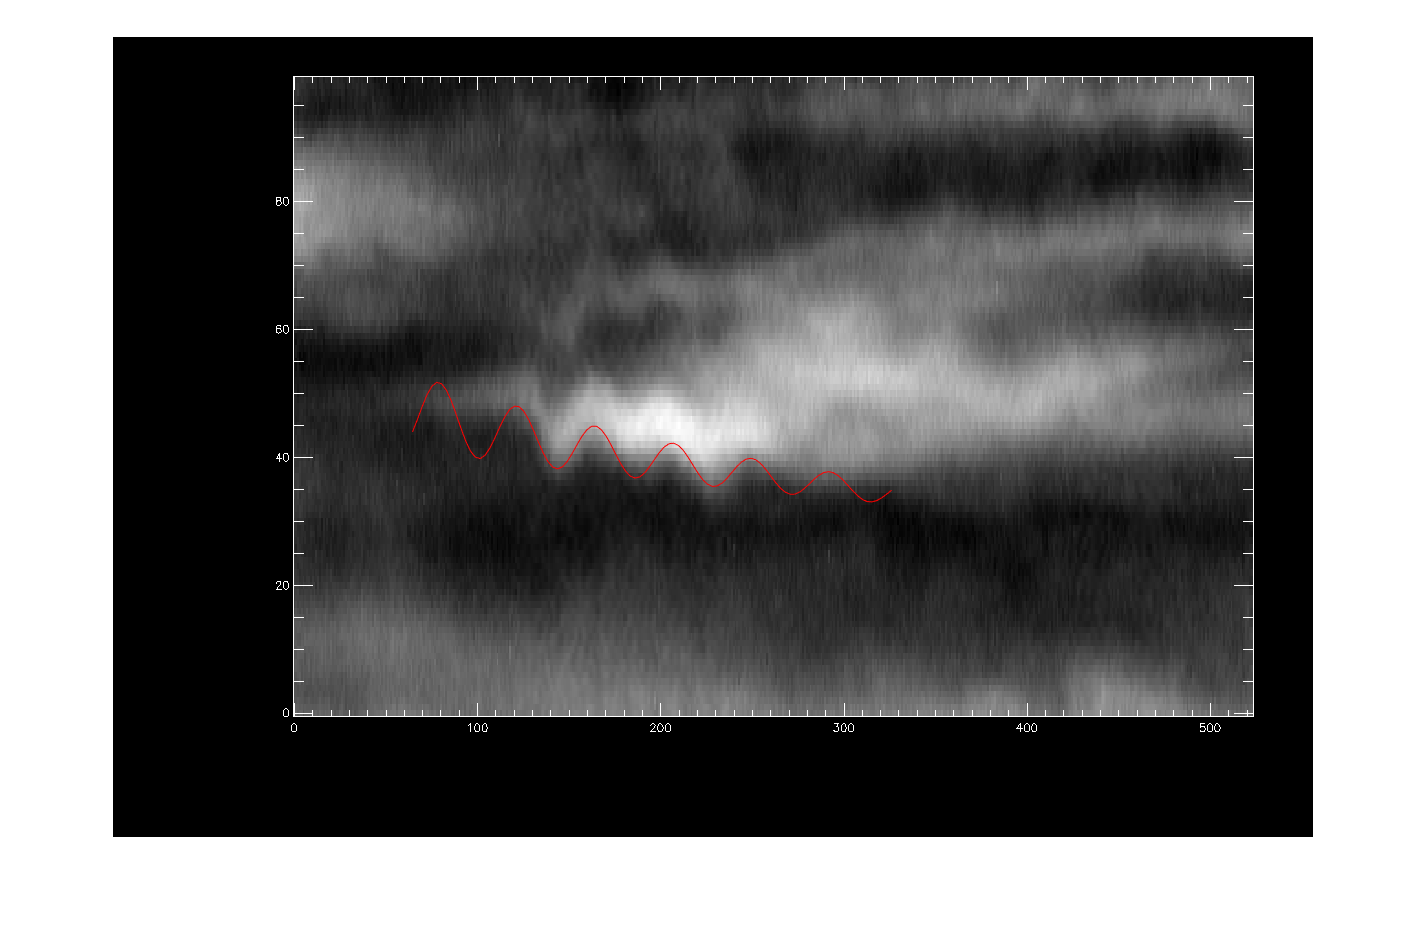

hold on
ytimes=-ytimes;
plot(xtimes,ytimes, 'r')